eeg_tr=x2323_eeg_strap.eeg2;
emg_tr=x2323_eeg_strap.eeg3;
eeg_tr=eeg_tr*(3.3/4096);
emg_tr=emg_tr*(3.3/4096);
f_data2=1/0.004;
t_data2=1/f_data2;
Time_d2=[0:1:length(eeg_tr)-1]*t_data2;

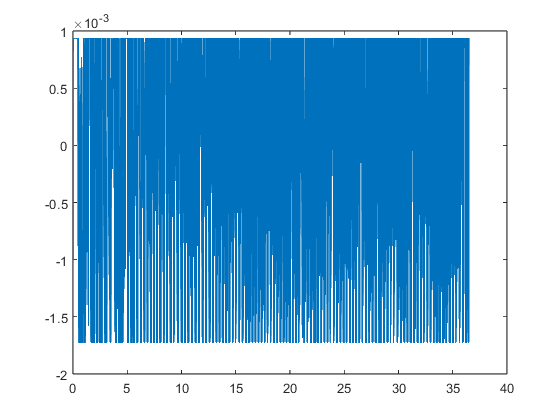

plot(Time_d2,eeg_tr)

eeg_tr_fft=fft(eeg_tr);
eeg_tr_fft(1)=0;
eeg_tr=ifft(eeg_tr_fft);
plot(Time_d2,eeg_tr)

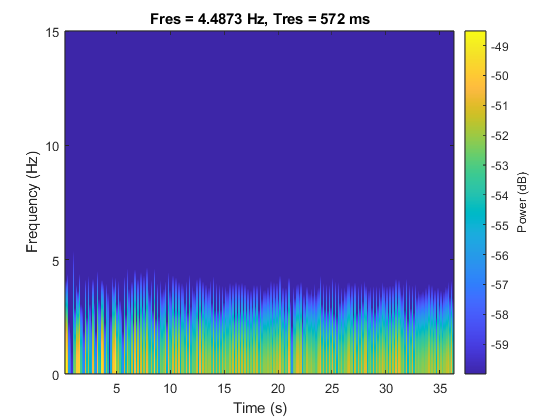

pspectrum(eeg_tr,f_data2,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-60)


eeg_smooth=smoothdata(eeg_tr,f_data2,"movmean")

eeg_smooth =     0.0027
    0.0027
    0.0027
    0.0025
    0.0020
    0.0012
    0.0007
    0.0017
    0.0027
    0.0027


pspectrum(eeg_smooth,f_data2,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-60)